

clc; clear;

% ----------------------------
% 1) Данные (синтетические)
% ----------------------------
years = (2010:2019)';
gdp     = [100, 103, 108, 112, 117, 122, 128, 135, 140, 145]';      % ВВП региона
investment = [20, 21, 22, 23, 23.5, 24, 24.5, 25.5, 26.0, 27]';      % Инвестиции
unemployment = [8.0, 7.9, 7.6, 7.4, 7.2, 6.9, 6.7, 6.5, 6.4, 6.2]'; % Безработица
inflation = [2.1, 2.0, 1.9, 2.1, 2.2, 2.0, 1.8, 1.9, 2.1, 2.0]';

% ----------------------------
% 2) Описательная статистика
% ----------------------------
meanGDP = mean(gdp);
stdGDP  = std(gdp);
minGDP  = min(gdp);
maxGDP  = max(gdp);

meanInv = mean(investment);
meanUnemp = mean(unemployment);
meanInfl = mean(inflation);

fprintf('Описательная статистика по ВВП (регион RegionX):\n');

Описательная статистика по ВВП (регион RegionX):


fprintf('  Среднее: %.2f\n', meanGDP);

  Среднее: 121.00


fprintf('  std: %.2f\n', stdGDP);

  std: 15.68


fprintf('  min..max: %.2f .. %.2f\n', minGDP, maxGDP);

  min..max: 100.00 .. 145.00


fprintf('\n');

% ----------------------------
% 3) Корреляционная матрица
% ----------------------------
corr_matrix = corr([gdp, investment, unemployment, inflation]);
disp('Корреляционная матрица (GDP, Investment, Unemployment, Inflation):');

Корреляционная матрица (GDP, Investment, Unemployment, Inflation):


disp(corr_matrix);

    1.0000    0.9858   -0.9915   -0.2012
    0.9858    1.0000   -0.9891   -0.1732
   -0.9915   -0.9891    1.0000    0.2359
   -0.2012   -0.1732    0.2359    1.0000




% ----------------------------
% 4) Регрессия OLS (Growth ~ Investment + Unemployment)
% Применяем к темпам роста ВВП: growth = d(V) / V_prev
% ----------------------------
growth = diff(gdp) ./ gdp(1:end-1);                 % рост ВВП по годам
X = [investment(1:end-1), unemployment(1:end-1)];   % два предиктора
Y = growth;                                          % целевая переменная

% Проверка наличия Toolbox перед использованием fitlm
if exist('fitlm', 'file') == 2
    mdl = fitlm(X, Y, 'VarNames', {'Investment','Unemployment','Growth'});
    disp('Линейная регрессия (Growth ~ Investment + Unemployment):');
    disp(mdl);
else
    error('Функция fitlm недоступна. Установите Statistics and Machine Learning Toolbox.');
end

Линейная регрессия (Growth ~ Investment + Unemployment):


Linear regression model:
    Growth ~ 1 + Investment + Unemployment

Estimated Coefficients:
                    Estimate        SE          tStat      pValue 
                    _________    _________    _________    _______

    (Intercept)     -0.012616      0.46763    -0.026979    0.97935
    Investment      0.0015087    0.0098593      0.15302     0.8834
    Unemployment    0.0027407     0.033386     0.082092    0.93724


Number of observations: 9, Error degrees of freedom: 6
Root Mean Squared Error: 0.00893
R-squared: 0.0337,  Adjusted R-Squared: -0.288
F-statistic vs. constant model: 0.105, p-value = 0.902



% Коэффициенты и p-значения
beta = mdl.Coefficients.Estimate;
pval = mdl.Coefficients.pValue;
fprintf('Коэффициенты регрессии и p-values:\n');

Коэффициенты регрессии и p-values:


fprintf('  Intercept: %.4f (p=%.4f)\n', beta(1), pval(1));

  Intercept: -0.0126 (p=0.9794)


fprintf('  Investment: %.4f (p=%.4f)\n', beta(2), pval(2));

  Investment: 0.0015 (p=0.8834)


fprintf('  Unemployment: %.4f (p=%.4f)\n', beta(3), pval(3));

  Unemployment: 0.0027 (p=0.9372)


fprintf('\n');

% ----------------------------
% 5) Тест на среднее: t-тест для роста (mean Growth = 0)
% ----------------------------
[H, P, CI, STATS] = ttest(Y, 0, 'Alpha', 0.05);
fprintf('Тест на среднее роста: H=%d, p-значение=%.4f, 95%% CI= [%.4f, %.4f], t-stat=%.4f\n', ...
    H, P, CI(1), CI(2), STATS.tstat);

Тест на среднее роста: H=1, p-значение=0.0000, 95% CI= [0.0361, 0.0482], t-stat=16.0790


fprintf('\n');

% ----------------------------
% 6) Бутстрэп для доверительного интервала среднего роста
% ----------------------------
nBoot = 1000;
N = length(Y);
bootMeans = zeros(nBoot,1);
rng(0); % фиксируем генератор для воспроизводимости

for b = 1:nBoot
    idx = randi(N, N, 1);
    bootMeans(b) = mean(Y(idx));
end
CI_boot = quantile(bootMeans, [0.025 0.975]);
meanGrowth = mean(Y);

fprintf('Бутстрэп: средний рост = %.4f, 95%% CI = [%.4f, %.4f]\n', meanGrowth, CI_boot(1), CI_boot(2));

Бутстрэп: средний рост = 0.0422, 95% CI = [0.0374, 0.0469]


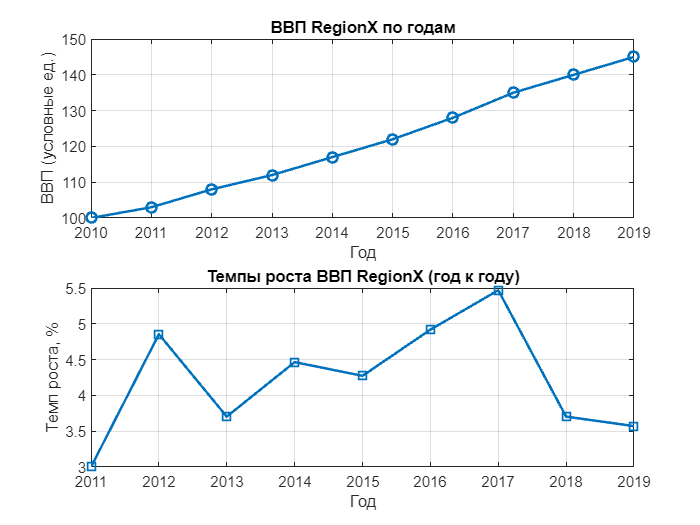

fprintf('\n');

% ----------------------------
% 7) Графики
% ----------------------------
% 7.1 GDP и рост по годам
figure(1); clf;
subplot(2,1,1);
plot(years, gdp, '-o', 'LineWidth', 1.5);
title('ВВП RegionX по годам');
xlabel('Год');
ylabel('ВВП (условные ед.)');
grid on;

subplot(2,1,2);
years_growth = years(2:end);
plot(years_growth, growth*100, '-s', 'LineWidth', 1.5);
title('Темпы роста ВВП RegionX (год к году)');
xlabel('Год');
ylabel('Темп роста, %');
grid on;

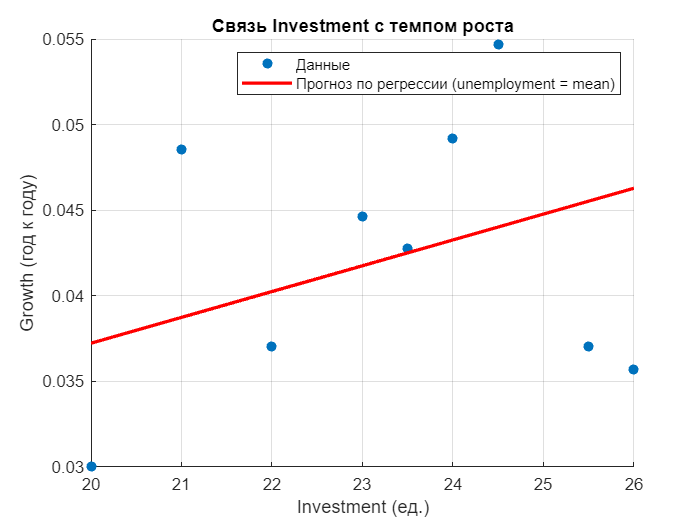


% 7.2 График регрессии: Investment vs Growth (Two predictors, наглядная часть)
figure(2); clf;
scatter(investment(1:end-1), growth, 'filled');
xlabel('Investment (ед.)');
ylabel('Growth (год к году)');
title('Связь Investment с темпом роста');
grid on; hold on;

% цветовая регрессия по двум предикторам упрощённо: возьмём регрессию из mdl
% Построим линию зависимости для фиксированного unemployment = его среднего
unempMean = mean(unemployment(1:end-1));
Xgrid = [linspace(min(investment(1:end-1)), max(investment(1:end-1)), 100)', ...
         unempMean * ones(100,1)];
Yhat = predict(mdl, Xgrid);
plot(Xgrid(:,1), Yhat, 'r-', 'LineWidth', 2);
legend('Данные', 'Прогноз по регрессии (unemployment = mean)');